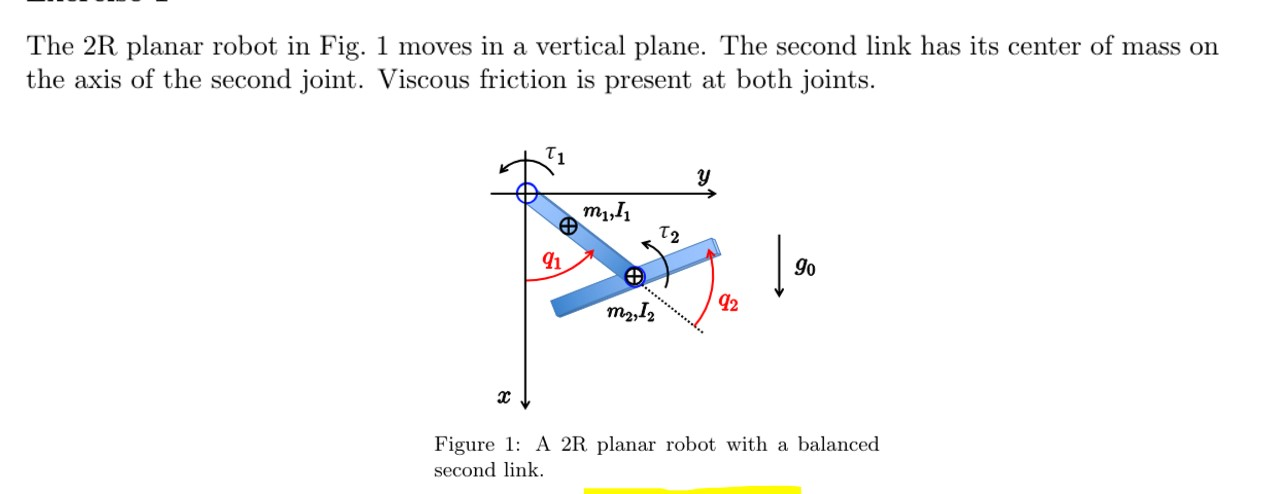

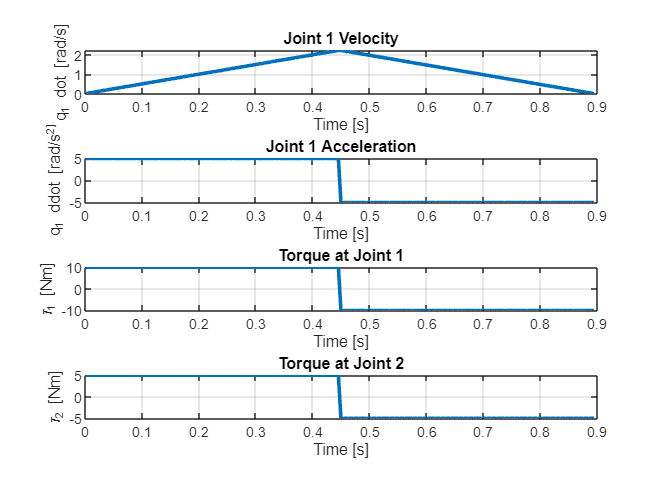

%% Time-Optimal Bang-Bang Motion for 2R Robot (Joint 2 held fixed)
clear; clc; close all;

%% Parameters (example values)
Delta     = 1.0;    % Desired change in q1 (rad)
I_tot     = 2.0;    % Total inertia seen by joint 1
I2        = 1.0;    % Inertia for joint 2
tau1_max  = 10.0;   % Max torque at joint 1 (Nm)
tau2_max  = 10.0;   % Max torque at joint 2 (Nm)

%% Compute the maximum feasible acceleration
a1 = tau1_max / I_tot;  % Limited by joint 1 torque
a2 = tau2_max / I2;     % Limited by joint 2 torque
a  = min(a1, a2);       % Overall max magnitude for q1''

%% Time-optimal bang-bang solution
% Half the motion is acceleration, half is deceleration
t1 = sqrt(Delta/a); 
T  = 2 * t1;

%% Discretize time
N    = 200;            % Number of sample points
tvec = linspace(0, T, N);

%% Preallocate for speed
q1_dot    = zeros(size(tvec));
q1_ddot   = zeros(size(tvec));
tau1      = zeros(size(tvec));
tau2      = zeros(size(tvec));

%% Compute profiles
for k = 1:N
    t = tvec(k);
    
    if t <= t1
        % Accelerating phase
        q1_ddot(k) = a;
        q1_dot(k)  = a * t;           % Integrate from 0
    else
        % Decelerating phase
        q1_ddot(k) = -a;
        q1_dot(k)  = a * (T - t);     % Triangular velocity profile
    end
    
    % From dynamics, torques follow directly:
    tau1(k) = I_tot * q1_ddot(k);
    tau2(k) = I2    * q1_ddot(k);
end

%% Plot results
figure('Name','Time-Optimal Bang-Bang','NumberTitle','off');

subplot(4,1,1)
plot(tvec, q1_dot, 'LineWidth',2); grid on;
xlabel('Time [s]'); ylabel('q_1 dot [rad/s]');
title('Joint 1 Velocity');

subplot(4,1,2)
plot(tvec, q1_ddot, 'LineWidth',2); grid on;
xlabel('Time [s]'); ylabel('q_1 ddot [rad/s^2]');
title('Joint 1 Acceleration');

subplot(4,1,3)
plot(tvec, tau1, 'LineWidth',2); grid on;
xlabel('Time [s]'); ylabel('\tau_1 [Nm]');
title('Torque at Joint 1');

subplot(4,1,4)
plot(tvec, tau2, 'LineWidth',2); grid on;
xlabel('Time [s]'); ylabel('\tau_2 [Nm]');
title('Torque at Joint 2');